# Resavanje problema klasifikacije primenom neuralne mreze

### Ucitavanje podataka

clc, clear, close all
rng(200)
load dataset1.mat


ulaz=pod(:, 1:2);
izlaz=pod(:, 3);

izlazOH=zeros(length(izlaz),3);
izlazOH(izlaz==1, 1)=1;
izlazOH(izlaz==2, 2)=1;
izlazOH(izlaz==3, 3)=1;

K1=ulaz(izlaz==1,:);
K2=ulaz(izlaz==2,:);
K3=ulaz(izlaz==3,:);

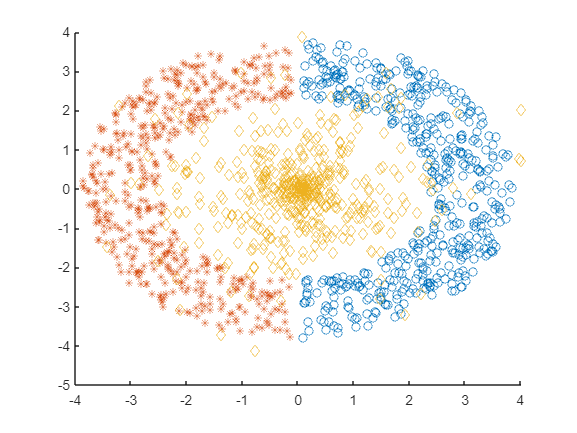

figure, hold all
plot(K1(:, 1), K1(:, 2), 'o')
plot(K2(:, 1), K2(:, 2), '*')
plot(K3(:, 1), K3(:, 2), 'd')

ulaz=ulaz';
izlazOH=izlazOH';
N=length(izlaz);
rnd= randperm(N);
rndTrening=rnd(1:0.8*N);
rndTest= rnd(0.8*N+1: N);

ulazTr=ulaz(:, rndTrening);
izlazTr=izlazOH(:, rndTrening);

ulazTe=ulaz(:, rndTest);
izlazTe=izlazOH(:, rndTest);

slojevi_UF=[2,1];
net1=patternnet(slojevi_UF);

for i = 1 : length(slojevi_UF)
    net1.layers{i}.transferFcn = 'tansig';
end
net1.layers{i+1}.transferFcn = 'softmax';
net1.divideFcn='';

slojevi2=[4,3];
net2=patternnet(slojevi2);

for i = 1 : length(slojevi2)
    net2.layers{i}.transferFcn = 'tansig';
end
net2.layers{i+1}.transferFcn = 'softmax';
net2.divideFcn='';


slojevi3=[40,50,10];


net3=patternnet(slojevi3);

for i = 1 : length(slojevi3)
    net3.layers{i}.transferFcn = 'tansig';
end
net3.layers{i+1}.transferFcn = 'softmax';
net3.divideFcn='';

net1.trainParam.epochs = 1000;
net1.trainParam.goal = 1e-5;
net1.trainParam.min_grad = 1e-6;
net1.trainParam.max_fail = 100;

net2.trainParam.epochs = 1000;
net2.trainParam.goal = 1e-5;
net2.trainParam.min_grad = 1e-6;
net2.trainParam.max_fail = 100;

net3.trainParam.epochs = 1000;
net3.trainParam.goal = 1e-5;
net3.trainParam.min_grad = 1e-6;
net3.trainParam.max_fail = 100;

rng(200);
net1=train(net1, ulazTr,izlazTr);

net2=train(net2, ulazTr,izlazTr);

net3=train(net3, ulazTr,izlazTr);

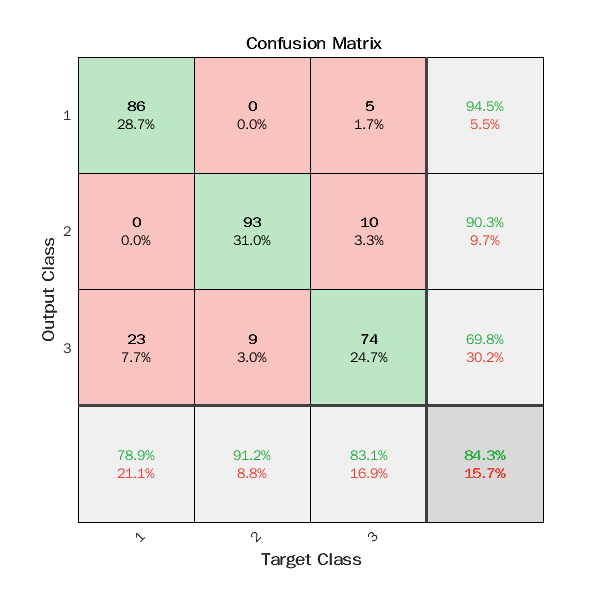

pred1=sim(net1, ulazTe);
figure, plotconfusion(izlazTe, pred1)

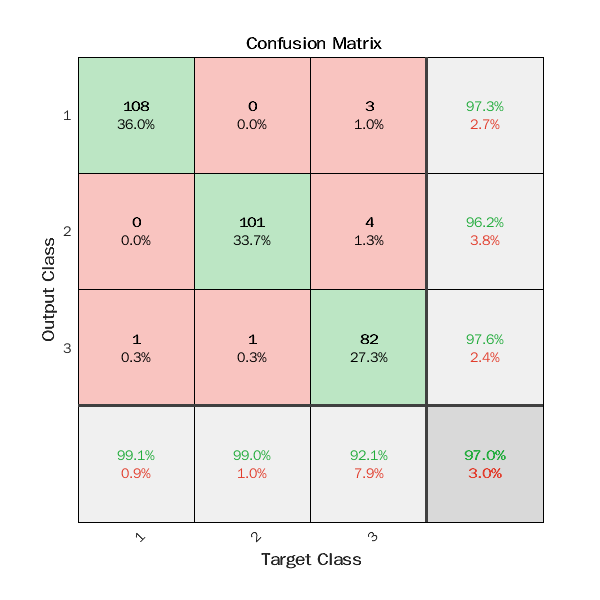

pred2=sim(net2, ulazTe);
figure, plotconfusion(izlazTe, pred2)

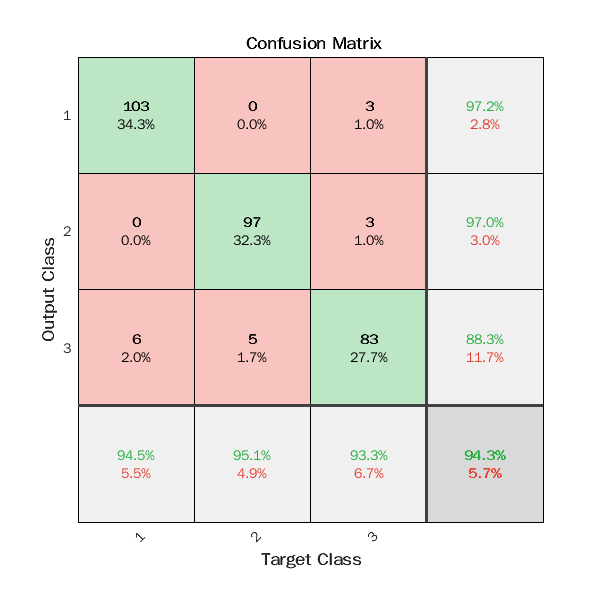


pred3=sim(net3, ulazTe);
figure, plotconfusion(izlazTe, pred3)

Ntest = 500;
ulazGO = [];
x1 = linspace(-4, 4, Ntest);
x2 = linspace(-4, 4, Ntest);

for x11 = x1
    pom = [x11*ones(1, Ntest); x2];
    ulazGO = [ulazGO, pom];
end

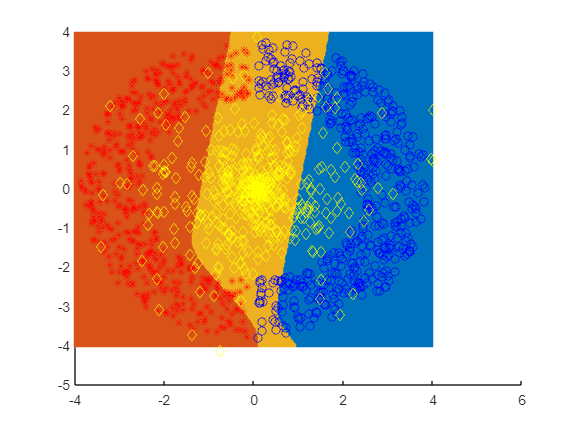

predGO = sim(net1, ulazGO);
[vr, klasa] = max(predGO);

K1go = ulazGO(:, klasa == 1);
K2go = ulazGO(:, klasa == 2);
K3go = ulazGO(:, klasa == 3);

figure, hold all
plot(K1go(1, :), K1go(2, :), '.')
plot(K2go(1, :), K2go(2, :), '.')
plot(K3go(1, :), K3go(2, :), '.')
plot(K1(:, 1), K1(:, 2), 'bo')
plot(K2(:, 1), K2(:, 2), 'r*')
plot(K3(:, 1), K3(:, 2), 'yd')

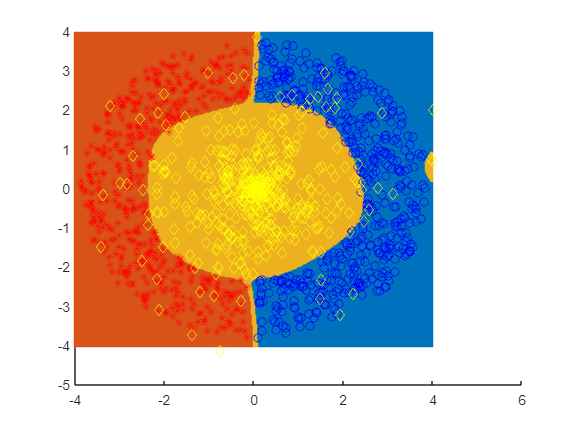

predGO = sim(net2, ulazGO);
[vr, klasa] = max(predGO);

K1go = ulazGO(:, klasa == 1);
K2go = ulazGO(:, klasa == 2);
K3go = ulazGO(:, klasa == 3);

figure, hold all
plot(K1go(1, :), K1go(2, :), '.')
plot(K2go(1, :), K2go(2, :), '.')
plot(K3go(1, :), K3go(2, :), '.')
plot(K1(:, 1), K1(:, 2), 'bo')
plot(K2(:, 1), K2(:, 2), 'r*')
plot(K3(:, 1), K3(:, 2), 'yd')

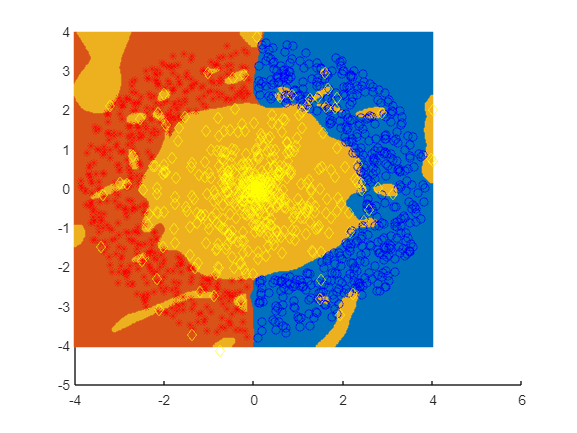

predGO = sim(net3, ulazGO);
[vr, klasa] = max(predGO);

K1go = ulazGO(:, klasa == 1);
K2go = ulazGO(:, klasa == 2);
K3go = ulazGO(:, klasa == 3);

figure, hold all
plot(K1go(1, :), K1go(2, :), '.')
plot(K2go(1, :), K2go(2, :), '.')
plot(K3go(1, :), K3go(2, :), '.')
plot(K1(:, 1), K1(:, 2), 'bo')
plot(K2(:, 1), K2(:, 2), 'r*')
plot(K3(:, 1), K3(:, 2), 'yd')